# Reto 1: Robot Cartesiano de 3GDL

## Objetivo

Para esta actividad se debe obtener el vector de velocidades lineal y angular para un robot de 3 grados de libertad (GDL) del tipo cartesiano:

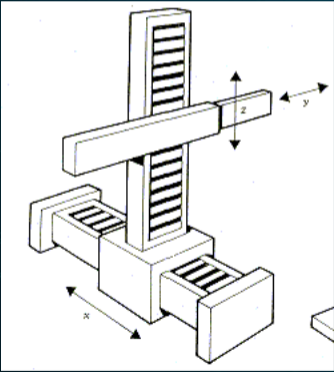

Imagen 1. Modelo

### Procedimiento

Primero se limpia la pantalla y valores, para poder declarar las variables simbólicas, es decir, no tienen un valor en específico.

clear all
close all
clc

syms l1(t) l2(t)  l3(t) t 

Posterioremente se hace la configuración del robot, 0 para junta rotacional, 1 para junta prismática, además de crear el vector de coordenadas articulares (Posición). En este caso, como son 3 articulaciones se colocan 3 unos por ser articulaciones prismáticas.

RP=[1 1 1];

Q= [l1, l2, l3];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(l1(t), l2(t), l3(t))



Sacando la derivada del vector de coordenadas articulares con la función diff, obtenemos la velocidad articular.

Qp= diff(Q, t);%diff() para derivadas con variable de referencia que no depende de otra: ejemplo el tiempo
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d         d         d       \
| -- l1(t), -- l2(t), -- l3(t) |
\ dt        dt        dt       /



Con la función size se declara el número de grados de libertad que tiene el robot con el vector RP previamente definido, siempre se coloca 2, ya que indica la dimensión de las columnas y se convierte a string para posteriormente declarar el nombre a las matrices.

GDL= size(RP,2);
GDL_str= num2str(GDL);


Para determinar las matrices de rotación se pone un sistema de referencia en cada articulación empezando desde la base del robot, se coloca el eje z en paralelo con el movimiento de esa articulación y se rota en las demás articulaciones, con esta rotación se determina el ángulo que se sustituirá en las siguientes matrices, dependiendo de en qué eje rotó el sistema de coordenadas.

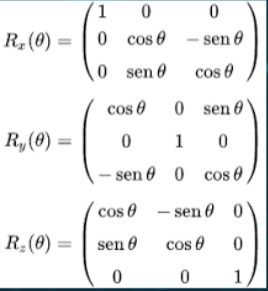

Imagen 2. Matrices de rotación

NOTA: si la rotación fue en la dirección de las manecillas del reloj el ángulo es negativo, de lo contrario es positivo.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1; 0; 0];
%Matriz de rotación de la junta 1 respecto a 0 .... rotó -90° se sustituye
R(:,:,1)= [0 0 -1;
           0 1 0;
           1 0 0];


%Articulación 2 
%Posición de la articulación 2 respecto a 0
P(:,:,2)= [0; 0;l2];
%Matriz de rotación de la junta 2 respecto a 0.... rotó -90º se sustituye
R(:,:,2)= [1  0 0;
           0  0 1;
           0 -1 0];


%Articulación 3 
%Posición de la articulación 3 respecto a 1
P(:,:,3)= [0; l3;0];
%Matriz de rotación de la junta 3 respecto a 1 (Matriz identidad)
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];


Se crea el vector de ceros y se inicializa tanto las matrices de transformación homogénea locales como las matrices de transformación homogénea globales

Vector_Zeros= zeros(1, 3);

A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);


Se inicializan los vectores de posición vistos desde el marco de referencia inercial con el número de grados de libertad

PO(:,:,GDL)= P(:,:,GDL);

Se Inicializan las matrices de rotación vistas desde el marco de referencia inercial con el número de grados de libertad

RO(:,:,GDL)= R(:,:,GDL) ;

Ahora en un ciclo for hará el procedimiento el número de veces de grados de libertad que tenga el robot. En este for se despliega las matrices de transformación locales y las globales, con un try catch se hace la excepción si el robot sólo cuenta con un grado de libertad. La mattriz global es la multiplicación de las locales.

for i = 1:GDL
    i_str= num2str(i);
    %locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i); %Caso específico cuando i=1 nos marcaría error en try
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))
    %Obtenemos la matriz de rotación "RO "y el vector de translación PO de la
    %matriz de transformación Homogénea global T(:,:,GDL)
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ 0, 0, -1, l1(t) \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0,   0   |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T1


/ 0, 0, -1, l1(t) \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0,   0   |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación local A2


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1,   0   |
|                 |
| 0, -1, 0, l2(t) |
|                 |
\ 0,  0, 0,   1   /



Matriz de Transformación global T2


/ 0, 1, 0, l1(t) - l2(t) \
|                        |
| 0, 0, 1,       0       |
|                        |
| 1, 0, 0,       0       |
|                        |
\ 0, 0, 0,       1       /



Matriz de Transformación local A3


/ 1, 0, 0,   0   \
|                |
| 0, 1, 0, l3(t) |
|                |
| 0, 0, 1,   0   |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T3


/ 0, 1, 0, l1(t) - l2(t) + l3(t) \
|                                |
| 0, 0, 1,           0           |
|                                |
| 1, 0, 0,           0           |
|                                |
\ 0, 0, 0,           1           /



Ya con esto se calcula el jacobiano lineal de forma diferencial, para esta matriz se deriva parcialmente l1, l2 y l3, respecto a los ejes. Con las derivadas acomodamos los valores y creamos la matriz del jacobiano.

%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a l1, l2, l3
Jv11= functionalDerivative(PO(1,1,GDL), l1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);
%Derivadas parciales de y respecto a l1, l2, l3
Jv21= functionalDerivative(PO(2,1,GDL), l1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);
%Derivadas parciales de z respecto a l1, l2, l3
Jv31= functionalDerivative(PO(3,1,GDL), l1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
pretty(jv_d);

/ 1, -1, 1 \
|          |
| 0,  0, 0 |
|          |
\ 0,  0, 0 /



Ahora se realiza el cálculo del jacobiano lineal de forma analítica, para esto se inicializa los jacobianos analíticos (lineal y angular).

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Nuevamente se utiliza un ciclo para construir los jacobianos, con una condición haca el procedimiento para una articulación rotacional o prismática, si en RP es 0 significa que es rotacional y con 1 es prismática,  dentro de la condición hay try catch para los grados de libertad del robot.

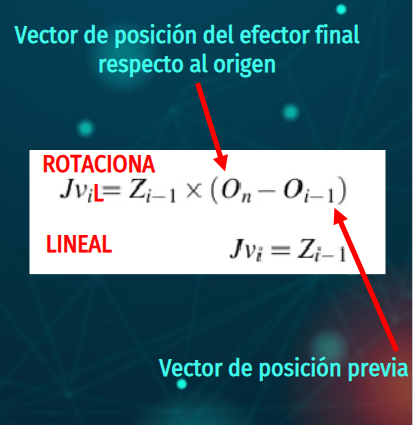

Fórmula 1.

Dependiendo del caso identificado, sea articulación rotacional o lineal, es la fórmula que se emplea.


for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad,
            % la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1]; %tercera columna de la matriz identidad
        end
            Jw_a(:,k)=[0,0,0];
     end
end


#### Resultados

Para finalmente desplegar los resultados con simplify y pretty para tener una visualización más entendible.

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);

Resultado de las operaciones hechas en el ciclo for para obtener el jacobiano lineal con los movimientos lineales en l2, l3 y l1.

disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, -1, 0 \
|          |
| 0,  0, 1 |
|          |
\ 1,  0, 0 /



Resultado del jacobiano angular obtenido de la forma analítica muestra, en este jacobiano, por no tener articulaciones que formen ángulos, ya que todas son prismáticas, la matriz aparece en ceros.

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 0, 0, 0 /



Al observar la velocidad lineal podemos comprobar que es correcto, porque tenemos movimiento en cada uno de los ejes x,y,z representado con la derivada en l1, l2 y l3  con respecto al tiempo, siendo la velocidad la derivada de la posición.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________ \
|    d       |
| - -- l2(t) |
|   dt       |
|            |
|  ________  |
|   d        |
|  -- l3(t)  |
|  dt        |
|            |
|  ________  |
|   d        |
|  -- l1(t)  |
\  dt        /



Nuevamente, por tener sólo articulaciones prismáticas obtenemos las siguientes velocidades angulares.

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /

